% % 11 algorithm 
% % 13 task 
% values = find(fit(:,13)==3);
% task3 = fit(values,:);
% save("fit_task3(1400)","task3");


## figures

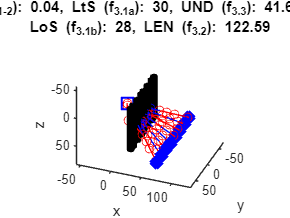

global eas;
global op;
clf;
n = newline;
taskID = 3;
switch taskID
    case 1
        firstTask();
    case 2
        fourthTask();
    case 3
        fifthTask();
end
task = eval("task" + num2str(taskID));
task = rankingEvaluation(task);
bestFitness = task(1,:);
index = task(1,15);
chrom = chroms{index};
conf = decodeIndividual(chrom);
tit = "IK (f_{1-2}): " + num2str(round(bestFitness(1,eas.fitIdx.ik),2)) +...
    ", LtS (f_{3.1a}): " + num2str(bestFitness(1,eas.fitIdx.nodes)) +...
    ", UND (f_{3.3}): " + num2str(bestFitness(1,eas.fitIdx.wiggly)) +...
    "%," + n + "LoS (f_{3.1b}): " + num2str(bestFitness(1,eas.fitIdx.nodesOnSegment))+...
    ", LEN (f_{3.2}): " + num2str(round(bestFitness(1,eas.fitIdx.totLength),2));
title(tit); 
drawProblem3D(conf)